Instituto Tecnológico de Estudios Superiores de Monterrey Campus Ciudad de México 

# **Reto: Tercera Entrega **

Lidia Paola Díaz Ramírez A01369117 

Jorge Yépez Frutos A01652661 

Axel González Carreto A01652775 

Yusdivia Molina Román A01653120 

Alex Álvaro Flores Contreras A01653320 

Modelación computacional de sistemas eléctricos 

Grupo: 13 

Profesores:

Yoel Ledo Mezquita

Víctor Francisco Robledo Rella 

David Alejandro Escárcega Centeno 

28 / Abril / 2020 

# **Introducción y definición del problema**

La malaria o fiebre cuarteana es una enfermedad parasitaria que involucra varios síntomas como fiebre alta, coma, dolor muscular, escalofríos, anemia, entre otras afecciones y, al año; se estiman que hay entre trescientos y quinientos millones de casos de dicho padecimiento y que alrededor de un millón muere a causa de este malestar.  

Gracias a estos datos, el objetivo de este trabajo es realizar una simulación del campo eléctrico de dos barras paralelas finitas, donde una tendrá un signo positivo y la otra negativo, para detectar si el paciente tiene dicha enfermedad. Esto se hace por medio de dielectroforesis, la cual consiste en pasar una muestra de sangre por este sistema, pues los glóbulos rojos se comportan de forma distinta si están contagiados.

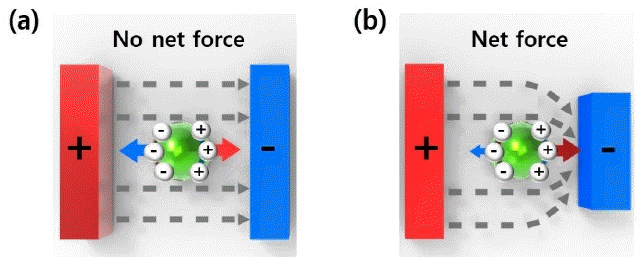

# **Contexto y ecuaciones**

Para graficar las dos barras finitas y hacer su cálculo, se decidió tomar las expresiones del campo eléctrico como referencia para calcular las componentes de *Ex* y *Ey *usando el principio de superposición el cual es: $E_{\textrm{tot}} =\bar{E_{1p} +} \bar{E_{2p} }$. 

Para sacar la componente total de *x* y *y *se aplicaron las siguientes ecuaciones: 

${\overrightarrow{E} }_Q =\frac{\textrm{KQ}}{r^2 }*\overset{\wedge }{v}$ lo que implicaría que la ecuación sea de la siguiente manera: ${\overrightarrow{E} }_Q =\frac{\textrm{KQ}}{r^2 }*\frac{\overset{\rightharpoonup }{v} }{\left|\overset{\rightharpoonup }{r} \right|}$

Con las ecuaciones ya definidas se emplea el principio de superposición con lo que darían las siguientes ecuaciones


$$F_{1p} =\left(x_p -x_1 \right)\hat{i} +\left(y_p -y_1 \right)\hat{j}$$



$$F_{2p} =\left(x_p -x_2 \right)\hat{i} +\left(y_p -y_2 \right)\hat{j}$$


A partir de aquí la expresión sería la siguiente: 

$E_{1p} =\frac{kq_1 }{{\left(r_{1p} \right)}^2 }*\frac{\overrightarrow{r_{2p} } }{{\left|r\right.}_{1p} \left|\right.}$ y simplificando queda: $\frac{kq_1 }{{\left(r_{1p} \right)}^3 }\left(x_p -x_1 \right)\hat{i} +\left(y_p -y_1 \right)\hat{j}$

Y lo mismo se aplicaría para $E_{2p}$ dando la siguiente ecuación: 


$$E_{2p} =$$

$$\frac{kq_1 }{{\left(r_{1p} \right)}^3 }\left(x_p -x_1 \right)\hat{i} +\left(y_p -y_1 \right)\hat{j}$$


Con esto ya se tiene una aproximación para la $E_{\textrm{total}} \;$en *x y y *dando lo siguiente: 

$r_{1p} =\sqrt{{\left(x_p -x_1 \right)}^2 +\left(x_p -x_2 \right)}$ y $r_{2p} =\sqrt{{\left(y_p -y_1 \right)}^2 +\left(y_p -y_2 \right)}$ 


$$E_{\textrm{totalx}} ={\textrm{kq}}_1 *\frac{x_p -x_1 }{{\left\lbrack {\left(x_p -x_1 \right)}^2 +{\left(y_p -y_1 \right)}^2 \right\rbrack }^{\frac{3}{2}} }+\frac{x_p -x_2 }{{\left\lbrack {\left(x_p -x_2 \right)}^2 +{\left(y_p -y_2 \right)}^2 \right\rbrack }^{\frac{3}{2}} }$$
 


$$E_{\textrm{totaly}} ={\textrm{kq}}_1 *\frac{y_p -y_1 }{{\left\lbrack {\left(x_p -x_1 \right)}^2 +{\left(y_p -y_1 \right)}^2 \right\rbrack }^{\frac{3}{2}} }+\frac{y_p -y_2 }{{\left\lbrack {\left(x_p -x_2 \right)}^2 +{\left(y_p -y_2 \right)}^2 \right\rbrack }^{\frac{3}{2}} }$$
 

# **Solución del problema**

clc;
clear;
close all;

Pedimos los **valores de entrada** con **controles**:

**a** = "distancia entre cargas (eje x)"

**N** = "número de puntos en la malla"

**d** = "distancia entre cargas (eje y)"

**n1** = "número de cargas positivas 2(n1)+1"

**n2** = "número de cargas negativas 2(n1)+1"

**q1** = "carga positiva"

**q2** = "carga negativa"

a =4;
N =0.5;
d =0.5;
n1 = 8;
n2 = 4;
q1 = 1;
q2 = -1;

Agregamos la** constante de Coulomb**:

k = 1;

 Sacamos las **x1** y **x2** apartir de "a" (distancia entre cargas):


$$\textrm{x1}=-\frac{a}{2}$$



$$\mathrm{x2}=\frac{a}{2}$$


x1 = -a/2;
x2 = a/2;

Primero usaremos 2 fors para el rango de valores de "x" y "y", $-10\le N\le 10$ y $-10\le N\le 10$ para que sea una malla rectangular; donde N representa de cuanto en cuanto ira aumentando el rango (número de puntos en la malla). Además se inicializan las variales sumx1, sumx2, sumy1 y sumy2 para posteriormente hacer uso del principio de superposición.

for x = -10:N:10 
    for y = -10:N:10 
        sumx2=0;
        sumx1=0;
        sumy2=0;
        sumy1=0;

Después, utilizaremos otro for para el rango de valores de "y1" en "n1", $-\textrm{n1}*d\le d\le \textrm{n1}*d$. Dentro de este for, calculamos "E1x" y "E2x", tomando en cuenta el cambio en "y1"; lo sumamos a nuestras valiables "sumx2" y "sumx1" correspondientemente. Finalmente, usamos plot() para gráficar cada carga de "n1"

        for y1 = -(n1*d):d:(n1*d)
            E1x=(k*q1*(x-x1)/((x-x1)^2+(y-y1)^2)^(3/2));
            E2x=(k*q2*(x-x2)/((x-x2)^2+(y-y1)^2)^(3/2));
            sumx2=sumx2+E2x;
            sumx1=sumx1+E1x;
            plot(x1,y1,'b--O')
        end
        

Repetimos el paso anterior pero ahora un for de rango de valores de "y2" en "n2"; del mismo modo, calculamos "Ey1" y "Ey2", tomando el cambio en "y2"; y lo sumamos a nuestras variables "sumy2" y "sumy1". Finalmente, gráficamos cada carga de "n2" usando plot().

        for y2 = -(n2*d):d:(n2*d)
            E1y=(k*q1*(y-y2)/((x-x1)^2+(y-y2)^2)^(3/2));
            E2y=(k*q2*(y-y2)/((x-x2)^2+(y-y2)^2)^(3/2));
            sumy2=sumy2+E2y;
            sumy1=sumy1+E1y;
            plot(x2,y2,'r--O')
        end
        

Posteriormente, usamos el principio de superposición para sacar "Ext" y "Eyt" (componentes del campo eléctrico en "x" y "y" respectivamente).

        SUMX= sumx1+sumx2;
        SUMY= sumy2+sumy1;
        

En seguida, normalizamos la magnitud del campo eléctrico para obtener flechas del mismo tamaño.

        magnitud = sqrt(SUMX^2+SUMY^2);
        Xfin= SUMX/magnitud;
        Yfin= SUMY/magnitud;

 Seguidamente, hacemos uso de la función quiver() para gráficar.

        quiver(x,y,Xfin,Yfin,'color','b','linewidth',1.2,'autoscalefactor',1);
    
        hold on
        
     end
   
end

Para finalizar, cuadriculamos en la parte de atrás.

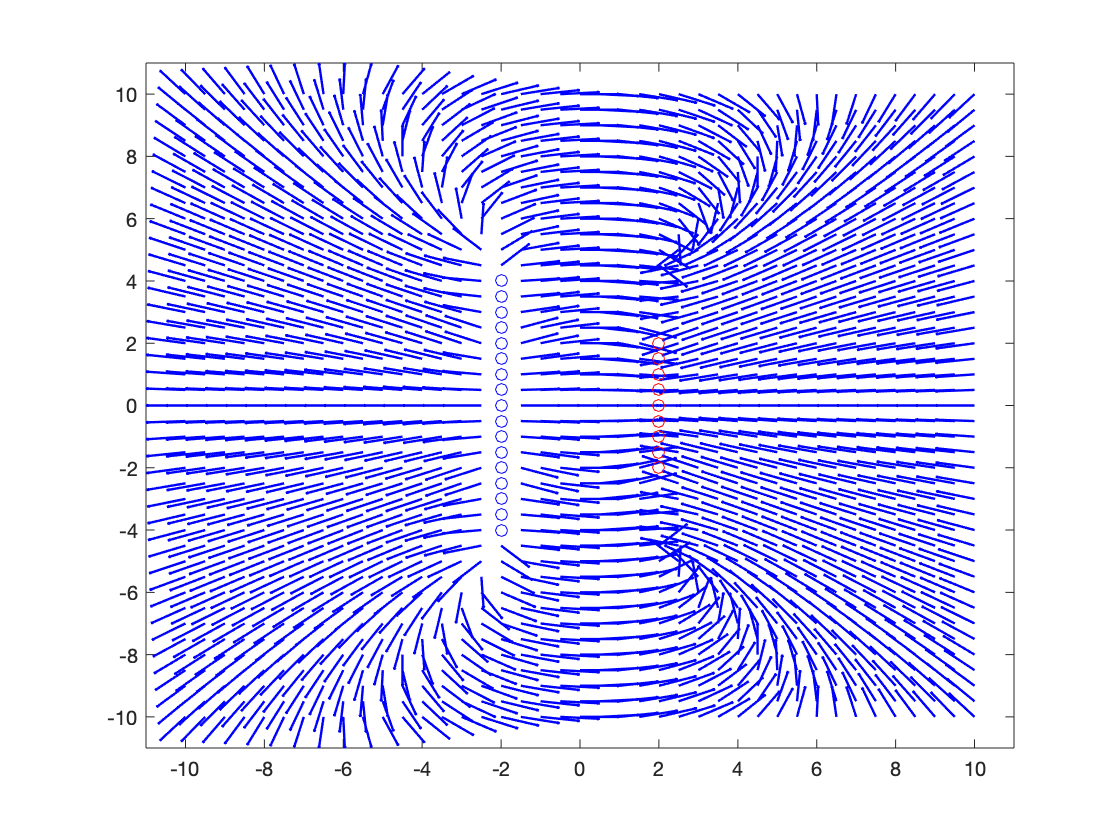

axis([-11 11 -11 11])

# **Resultados y discusión**

Captura del cálculo de los valores en diferentes puntos. Donde "n1" = 6 , "n2" = 6, "a" = 6, "N" = 0.5 y "d" = 0.5

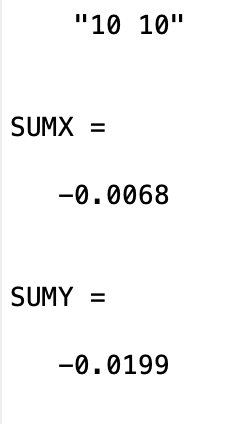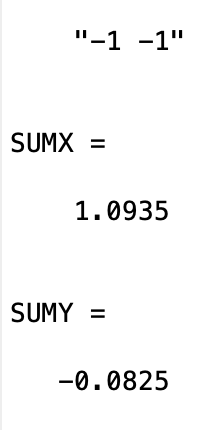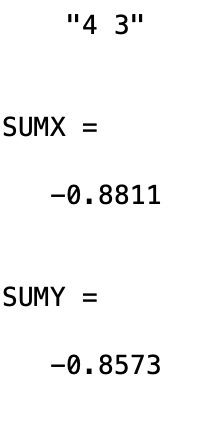

Captura de "n1" = 8 , "n2" = 4, "a" = 6, "N" = 0.5 y "d" = 0.5:    **d = 0.083 a**

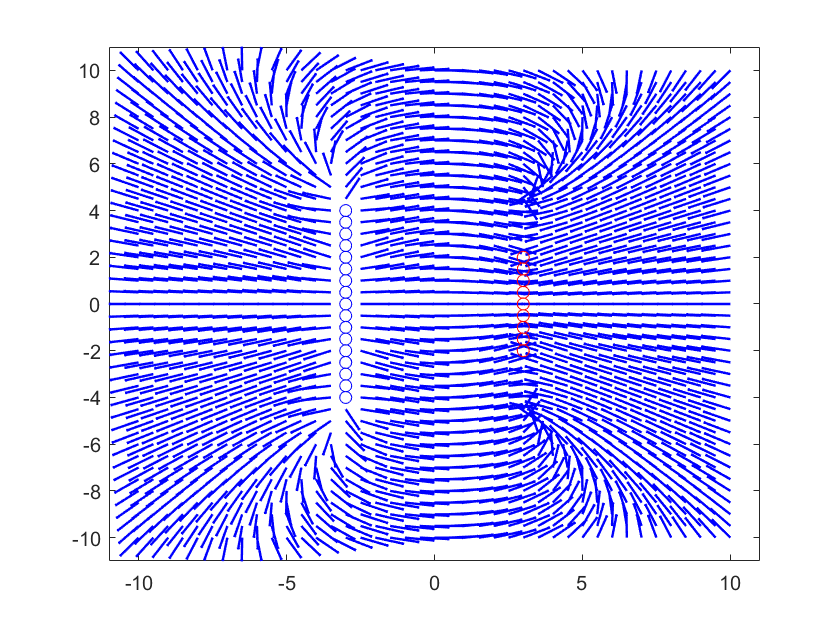

Captura de "n1" = 8 , "n2" = 4, "a" = 4, "N" = 0.5 y "d" = 1:    **    d = 0.25 a**

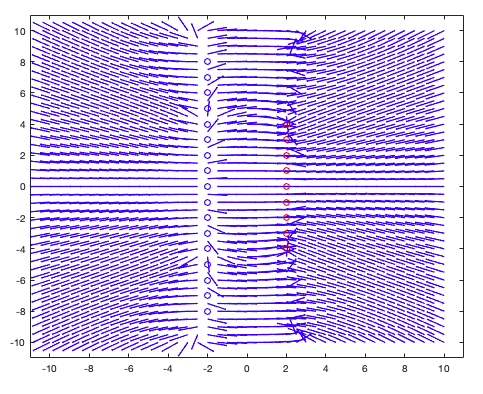

Captura de "n1" = 8 , "n2" = 4, "a" = 4, "N" = 0.5 y "d" = 2: **   d = 0.5 a**

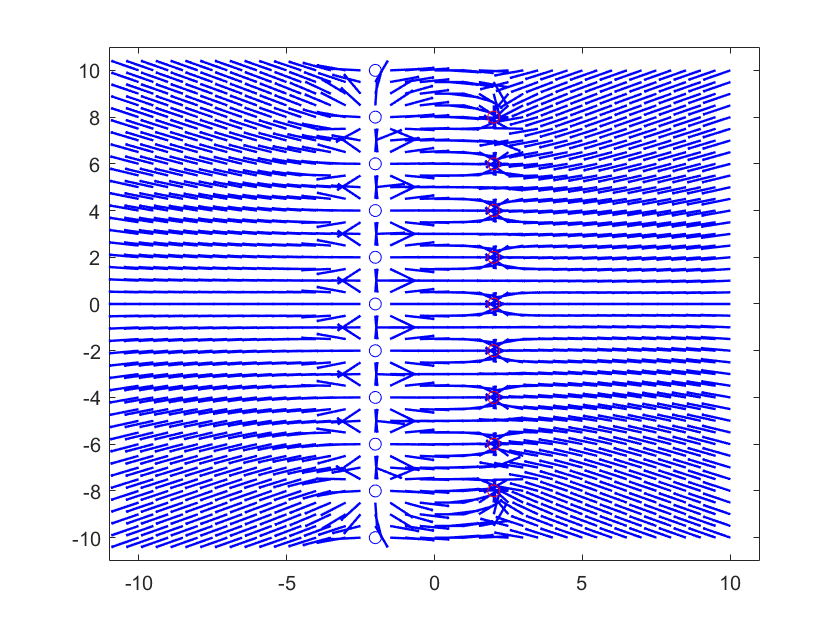

Captura de "n1" = 8 , "n2" = 4, "a" = 4, "N" = 0.5 y "d" = 4: **   d =  a**

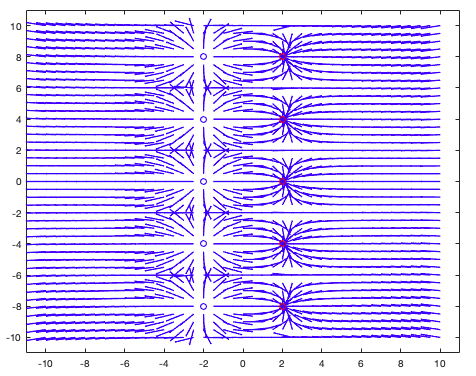

Podemos observar que mientras la "d" (distancia entre cargas) sea menor, el campo eléctrico será más parecido a uno de placas paralelas; así mismo, como queremos producir un campo no uniforme para poder separar glóbulos rojos sanos de los infectados; "n1" debe ser mayor a "n2", y "d" debe ser lo más pequeña posible con respecto a "a" para producir un campo NO uniforme. 

# **Conclusiones**

Actualmente vivimos en un mundo en el que la tecnología esta tomando un lugar importante en nuestras vidas, y en este caso en el área de la salud, ya que nos ayuda a analizar, experimentar y entender los sucesos de la naturaleza.

La dielectroforesis  es un movimiento de las partículas causado por los efectos de polarización en un campo eléctrico no uniforme, el cual ayuda a diagnosticar la malaria, usando una muestra de sangre del paciente.

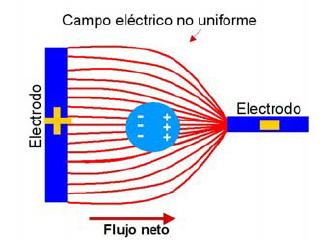

Para poder lograr nuestro objetivo tuvimos que poner en práctica los conocimientos adquiridos en clases como el funcionamiento de un campo eléctrico, junto con sus elementos y el principio de superposición, aunque al comienzo de la primera semana no se tenian tan comprendidos estos conceptos, con el resultado y entrega nos logramos dar cuenta de como poco a poco fuimos comprendiendo estos principios, y que el resultado fue lo que se esperaba, lograr una simulación de lo que sería la dielectroforesis.

**Primer entregable:**

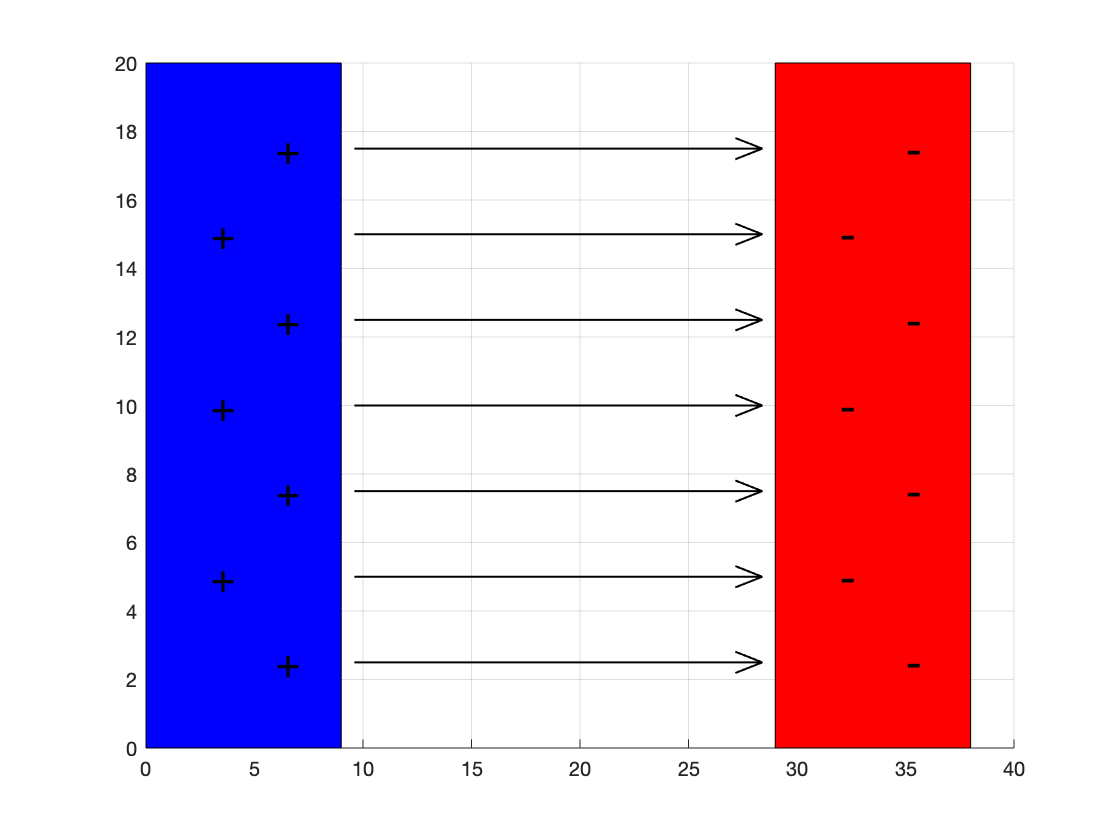

**Segundo entregable:**

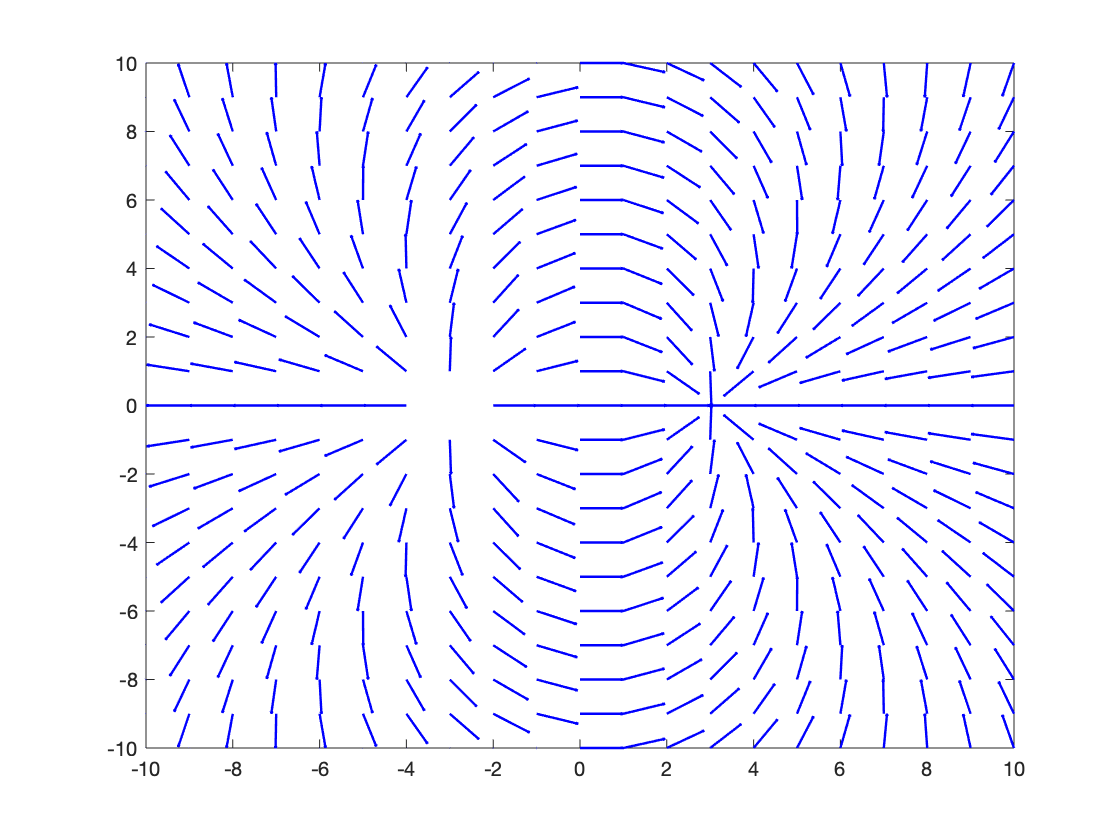

**Tercer entegrable:**

Lo que se logro al realizar este reto es demostrar la gran importancia que tiene la fisica, y las aplicaciones que se le pueden dar a la electrostatica, y por más simples que parezcan las interacciones electricas nos pueden ayudar a detectar enfermedades y buscar una solución a estas.

# **Referencias**

DrTango I. (2019). Malaria. marzo 27, 2020, de MedlinePlus Recuperado de: [https://medlineplus.gov/spanish/ency/article/000621.htm](https://medlineplus.gov/spanish/ency/article/000621.htm)

Palomares, M. (2007). Campo eléctrico no uniforme. ResearchGate. Recuperado de : [https://www.researchgate.net/figure/Movimiento-de-una-particula-en-un-campo-electrico-no-uniforme-dielectroforesis-positiva_fig1_238088717](https://www.researchgate.net/figure/Movimiento-de-una-particula-en-un-campo-electrico-no-uniforme-dielectroforesis-positiva_fig1_238088717)